t = out.truePose.Estimatex.time;

true_x = out.truePose.Estimatex.data;
true_y = out.truePose.Estimatey.data;
true_z = out.truePose.Estimatez.data;
true_roll = out.truePose.EstimateRoll.data;
true_pitch = out.truePose.EstimatePitch.data;
true_yaw = out.truePose.EstimateYaw.data;
sim_x = out.simPose.x.data;
sim_y = out.simPose.y.data;
sim_z = out.simPose.z.data;
sim_roll = out.simPose.roll.data;
sim_pitch = out.simPose.pitch.data;
sim_yaw = out.simPose.yaw.data;
input_x_sim = input_x(1:length(sim_x),2);

Unrecognized function or variable 'input_x'.

input_y_sim = input_y(1:length(sim_x),2);
input_z_sim = input_z(1:length(sim_x),2);
input_yaw_sim = input_yaw(1:length(sim_x),2);

RMSE_x = rmse(sim_x, true_x)*1000
RMSE_y = rmse(sim_y, true_y)*1000
RMSE_z = rmse(sim_z, true_z)*1000
RMSE_roll = rad2deg(rmse(sim_roll, true_roll))
RMSE_pitch = rad2deg(rmse(sim_pitch, true_pitch))
RMSE_yaw = rad2deg(rmse(sim_yaw, true_yaw))

error_x = sim_x - true_x;
% error_x = timeseries(error_x,time,"Name",error_x)
[c, lags] = xcorr(input_x_sim, error_x,100,'normalized');
% [c, lags] = xcorr(error_y, input_y_data,100,'normalized');
% [c, lags] = xcorr(error_z, input_z_data,100,'normalized');
stem(lags, c)
id_sim = iddata([sim_x, sim_y, sim_z, sim_roll, sim_pitch, sim_yaw],[input_x_sim, input_y_sim, input_z_sim, input_yaw_sim],0.01);
id_true = iddata([true_x, true_y, true_z, true_roll, true_pitch, true_yaw], [input_x_sim, input_y_sim, input_z_sim, input_yaw_sim], 0.01);
compare(id_true, id_sim)

x_t_start = 127;
x_t_end = 150;
y_t_start = 127;
y_t_end = 150;
z_t_start = 127;
z_t_end = 150;
yaw_t_start = 147;
yaw_t_end = 170;

x_i0 = find(t==x_t_start);
x_if = find(t==x_t_end);
y_i0 = find(t==y_t_start);
y_if = find(t==y_t_end);
z_i0 = find(t==z_t_start);
z_if = find(t==z_t_end);
yaw_i0 = find(t==yaw_t_start);
yaw_if = find(t==yaw_t_end);

red = [215/256,48/256,39/256];
orange = [253/256,174/256,97/256];
blue = [69/256,117/256,180/256];
black = [0 0 0];

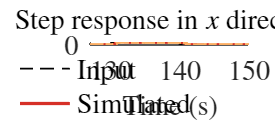

hfig1 = figure(1); clf; hold on;  % save the figure handle in a variable

plot(t(x_i0:x_if),input_x_sim(x_i0:x_if), 'Color', black, 'LineStyle','--','LineWidth',1);
plot(t(x_i0:x_if),sim_x(x_i0:x_if), 'Color', red, 'LineStyle','-','LineWidth',2);
plot(t(x_i0:x_if),true_x(x_i0:x_if), 'Color', orange, 'LineStyle','-.','LineWidth',2);
xlabel('Time (s)')
ylabel('$x$ position (m)')
legend('Input', 'Simulated', 'Experimental')
title('Step response in $x$ direction')
fname = 'myfigure';

picturewidth = 20; % set this parameter and keep it forever
hw_ratio = 0.45; % feel free to play with this ratio
set(findall(hfig1,'-property','FontSize'),'FontSize',17) % adjust fontsize to your document

set(findall(hfig1,'-property','Box'),'Box','off') % optional
set(findall(hfig1,'-property','Interpreter'),'Interpreter','latex') 
set(findall(hfig1,'-property','TickLabelInterpreter'),'TickLabelInterpreter','latex')
set(hfig1,'Units','centimeters','Position',[3 3 picturewidth hw_ratio*picturewidth])
pos = get(hfig1,'Position');
set(hfig1,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[pos(3), pos(4)])
%print(hfig,fname,'-dpdf','-painters','-fillpage')
print(hfig1,fname,'-dpng','-painters')

hold off;

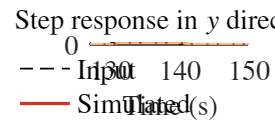

hfig2 = figure(2); clf; hold on;  % save the figure handle in a variable

plot(t(y_i0:y_if),input_y_sim(y_i0:y_if), 'Color', black, 'LineStyle','--','LineWidth',1);
plot(t(y_i0:y_if),sim_y(y_i0:y_if), 'Color', red, 'LineStyle','-','LineWidth',2);
plot(t(y_i0:y_if),true_y(y_i0:y_if), 'Color', orange, 'LineStyle','-.','LineWidth',2);
xlabel('Time (s)')
ylabel('$y$ position (m)')
legend('Input', 'Simulated', 'Experimental')
title('Step response in $y$ direction')
fname = 'myfigure';

picturewidth = 20; % set this parameter and keep it forever
hw_ratio = 0.45; % feel free to play with this ratio
set(findall(hfig2,'-property','FontSize'),'FontSize',17) % adjust fontsize to your document

set(findall(hfig2,'-property','Box'),'Box','off') % optional
set(findall(hfig2,'-property','Interpreter'),'Interpreter','latex') 
set(findall(hfig2,'-property','TickLabelInterpreter'),'TickLabelInterpreter','latex')
set(hfig2,'Units','centimeters','Position',[3 3 picturewidth hw_ratio*picturewidth])
pos = get(hfig2,'Position');
set(hfig2,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[pos(3), pos(4)])
%print(hfig,fname,'-dpdf','-painters','-fillpage')
print(hfig2,fname,'-dpng','-painters')

hold off;

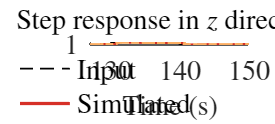

hfig3 = figure(3); clf; hold on;  % save the figure handle in a variable

plot(t(z_i0:z_if),input_z_sim(z_i0:z_if), 'Color', black, 'LineStyle','--','LineWidth',1);
plot(t(z_i0:z_if),sim_z(z_i0:z_if), 'Color', red, 'LineStyle','-','LineWidth',2);
plot(t(z_i0:z_if),true_z(z_i0:z_if), 'Color', orange, 'LineStyle','-.','LineWidth',2);
xlabel('Time (s)')
ylabel('$z$ position (m)')
legend('Input', 'Simulated', 'Experimental')
title('Step response in $z$ direction')
fname = 'myfigure';

picturewidth = 20; % set this parameter and keep it forever
hw_ratio = 0.45; % feel free to play with this ratio
set(findall(hfig3,'-property','FontSize'),'FontSize',17) % adjust fontsize to your document

set(findall(hfig3,'-property','Box'),'Box','off') % optional
set(findall(hfig3,'-property','Interpreter'),'Interpreter','latex') 
set(findall(hfig3,'-property','TickLabelInterpreter'),'TickLabelInterpreter','latex')
set(hfig3,'Units','centimeters','Position',[3 3 picturewidth hw_ratio*picturewidth])
pos = get(hfig3,'Position');
set(hfig3,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[pos(3), pos(4)])
%print(hfig,fname,'-dpdf','-painters','-fillpage')
print(hfig3,fname,'-dpng','-painters')

hold off;

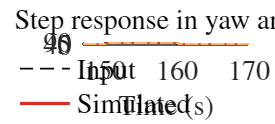

hfig4 = figure(4); clf; hold on;  % save the figure handle in a variable

plot(t(yaw_i0:yaw_if),input_yaw_sim(yaw_i0:yaw_if), 'Color', black, 'LineStyle','--','LineWidth',1);
plot(t(yaw_i0:yaw_if),sim_yaw(yaw_i0:yaw_if)*(180/pi), 'Color', red, 'LineStyle','-','LineWidth',2);
plot(t(yaw_i0:yaw_if),true_yaw(yaw_i0:yaw_if)*(180/pi), 'Color', orange, 'LineStyle','-.','LineWidth',2);
xlabel('Time (s)')
ylabel('Yaw rotation angle (Deg)')
yticks([0, 45, 90])
legend('Input', 'Simulated', 'Experimental')
title('Step response in yaw angle')
fname = 'myfigure';

picturewidth = 20; % set this parameter and keep it forever
hw_ratio = 0.45; % feel free to play with this ratio
set(findall(hfig4,'-property','FontSize'),'FontSize',17) % adjust fontsize to your document

set(findall(hfig4,'-property','Box'),'Box','off') % optional
set(findall(hfig4,'-property','Interpreter'),'Interpreter','latex') 
set(findall(hfig4,'-property','TickLabelInterpreter'),'TickLabelInterpreter','latex')
set(hfig4,'Units','centimeters','Position',[3 3 picturewidth hw_ratio*picturewidth])
pos = get(hfig4,'Position');
set(hfig4,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[pos(3), pos(4)])
%print(hfig,fname,'-dpdf','-painters','-fillpage')
print(hfig4,fname,'-dpng','-painters')

hold off;

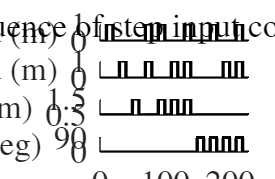

hfig5 = figure(5); clf; hold on;  % save the figure handle in a variable


subplot(4, 1, 1)
plot(t,input_x_sim, 'Color', black, 'LineStyle','-','LineWidth',2);
xticks([])
yticks([0, 1])
ylabel('$x$ command (m)', 'Rotation', 0)
subplot(4, 1, 2)
plot(t,input_y_sim, 'Color', black, 'LineStyle','-','LineWidth',2);
xticks([])
yticks([0, 1])
ylabel('$y$ command (m)', 'Rotation', 0)
subplot(4, 1, 3)
plot(t,input_z_sim, 'Color', black, 'LineStyle','-','LineWidth',2);
xticks([])
ylabel('$z$ command (m)', 'Rotation', 0)
yticks([0.5, 1.5])
ylim([0.49 1.5])
subplot(4, 1, 4)
plot(t,input_yaw_sim, 'Color', black, 'LineStyle','-','LineWidth',2);
xlabel('Time (s)')
ylabel('Yaw command (deg)', 'Rotation', 0)
yticks([0, 90])
fname = 'myfigure';

sgtitle('Full sequence of step input commands')

picturewidth = 20; % set this parameter and keep it forever
hw_ratio = 0.65; % feel free to play with this ratio
set(findall(hfig5,'-property','FontSize'),'FontSize',20) % adjust fontsize to your document

set(findall(hfig5,'-property','Box'),'Box','off') % optional
set(findall(hfig5,'-property','Interpreter'),'Interpreter','latex') 
set(findall(hfig5,'-property','TickLabelInterpreter'),'TickLabelInterpreter','latex')
set(hfig5,'Units','centimeters','Position',[3 3 picturewidth hw_ratio*picturewidth])
pos = get(hfig5,'Position');
set(hfig5,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[pos(3), pos(4)])
%print(hfig,fname,'-dpdf','-painters','-fillpage')
print(hfig5,fname,'-dpng','-painters')

hold off;

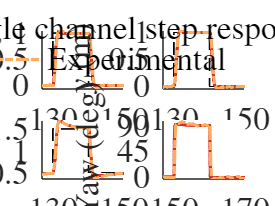

hfig5 = figure(5); clf; hold on;  % save the figure handle in a variable


subplot(2, 2, 1), hold on
plot(t(x_i0:x_if),input_x_sim(x_i0:x_if), 'Color', black, 'LineStyle','--','LineWidth',1);
plot(t(x_i0:x_if),sim_x(x_i0:x_if), 'Color', red, 'LineStyle','-','LineWidth',2);
plot(t(x_i0:x_if),true_x(x_i0:x_if), 'Color', orange, 'LineStyle','-.','LineWidth',2);
ylabel('$x$ (m)')
hold off
subplot(2, 2, 2), hold on
plot(t(y_i0:y_if),input_y_sim(y_i0:y_if), 'Color', black, 'LineStyle','--','LineWidth',1);
plot(t(y_i0:y_if),sim_y(y_i0:y_if), 'Color', red, 'LineStyle','-','LineWidth',2);
plot(t(y_i0:y_if),true_y(y_i0:y_if), 'Color', orange, 'LineStyle','-.','LineWidth',2);
ylabel('$y$ (m)')
legend('Input', 'Simulated', 'Experimental','Orientation', 'horizontal')
hold off
subplot(2, 2, 3), hold on
plot(t(z_i0:z_if),input_z_sim(z_i0:z_if), 'Color', black, 'LineStyle','--','LineWidth',1);
plot(t(z_i0:z_if),sim_z(z_i0:z_if), 'Color', red, 'LineStyle','-','LineWidth',2);
plot(t(z_i0:z_if),true_z(z_i0:z_if), 'Color', orange, 'LineStyle','-.','LineWidth',2);
xlabel('Time (s)')
ylabel('$z$ (m)')
yticks([0.5, 1, 1.5])
hold off
subplot(2, 2, 4), hold on
plot(t(yaw_i0:yaw_if),input_yaw_sim(yaw_i0:yaw_if), 'Color', black, 'LineStyle','--','LineWidth',1);
plot(t(yaw_i0:yaw_if),sim_yaw(yaw_i0:yaw_if)*(180/pi), 'Color', red, 'LineStyle','-','LineWidth',2);
plot(t(yaw_i0:yaw_if),true_yaw(yaw_i0:yaw_if)*(180/pi), 'Color', orange, 'LineStyle','-.','LineWidth',2);
xlabel('Time (s)')
ylabel('Yaw (deg)')
yticks([0, 45, 90])
hold off
fname = 'myfigure';

sgtitle({'Single channel step responses', ''})

picturewidth = 20; % set this parameter and keep it forever
hw_ratio = 0.75; % feel free to play with this ratio
set(findall(hfig5,'-property','FontSize'),'FontSize',20) % adjust fontsize to your document

set(findall(hfig5,'-property','Box'),'Box','off') % optional
set(findall(hfig5,'-property','Interpreter'),'Interpreter','latex') 
set(findall(hfig5,'-property','TickLabelInterpreter'),'TickLabelInterpreter','latex')
set(hfig5,'Units','centimeters','Position',[3 3 picturewidth hw_ratio*picturewidth])
pos = get(hfig5,'Position');
set(hfig5,'PaperPositionMode','Auto','PaperUnits','centimeters','PaperSize',[pos(3), pos(4)])
%print(hfig,fname,'-dpdf','-painters','-fillpage')
print(hfig5,fname,'-dpng','-painters')

hold off;